# Tarea 2

Día 2, Diapositiva 52

*I. Santos-Ruiz & F.R. López-Estrada*

Modelo en tiempo continuo

A = [0,1;-2,-3]; B = [0;1]; C = [0,1];

Buscamos un periodo de muestreo adecuado:

Recordar que $\tau=-\frac{1}{\mathrm{Re}(\lambda)}$

lambda = eig(A)

lambda =     -1
    -2


tau = -1./real(lambda)

tau =     1.0000
    0.5000


Ts_max = min(tau)/10

Ts_max = 0.0500

Ts = 0.01;

Obtenemos la matrices en tiempo discreto:

discreto = c2d(ss(A,B,C,0),Ts);
Ad = discreto.a;
Bd = discreto.b;

Parámetros del ruido:

Q = eye(2)*1e-9;
R = 0.01;

### Filtrado con el código de licencia BeerWare

Creamos el filtro de Kalman:

kf = KalmanFilter(Ad,Bd,C,Q,R);

Mediante simulación obtenemos la salida y le añadimos ruido:

[t,x] = ode45(@(t,x) A*x+B*heaviside(t),0:Ts:500*Ts,[0;0]);
y = x(:,2);
y = y + 0.1*randn(size(y));
u = heaviside(t);

Probamos el filtro:

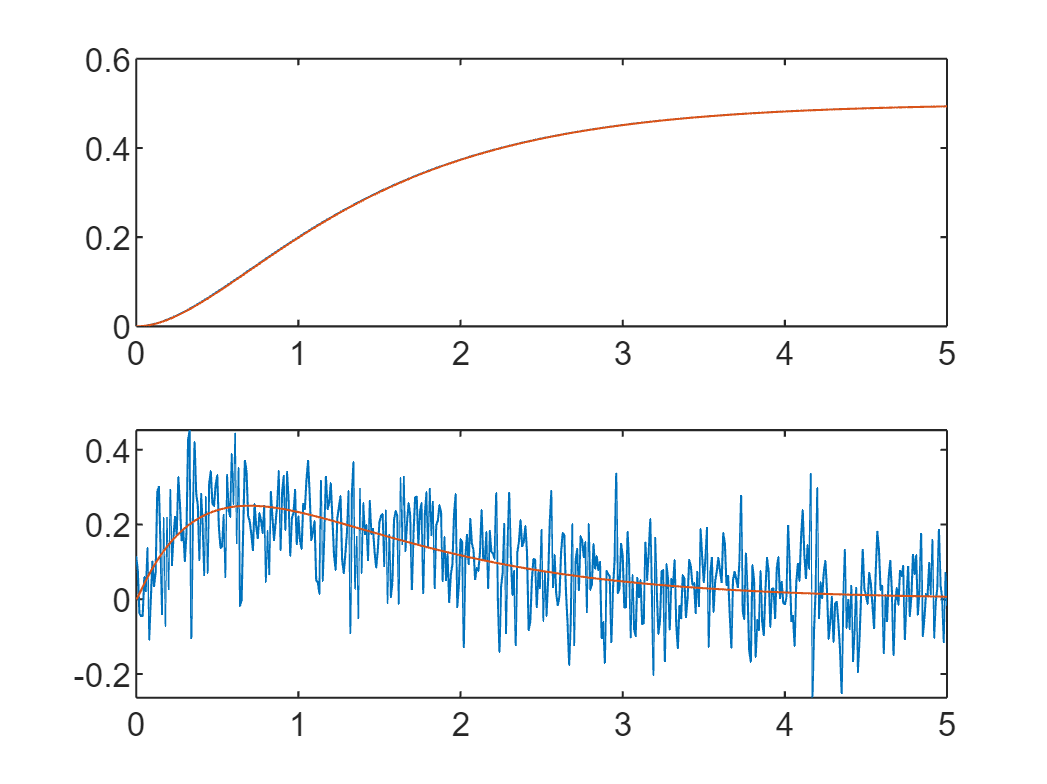

kf.initialize([0;0],eye(2)*1e-6)
xhat = kf.estimate(u',y');
figure(1)
subplot(211); plot(t,x(:,1),t,xhat(1,:))
subplot(212); plot(t,y,t,xhat(2,:))

### Filtrado con el Control Systems Toolbox

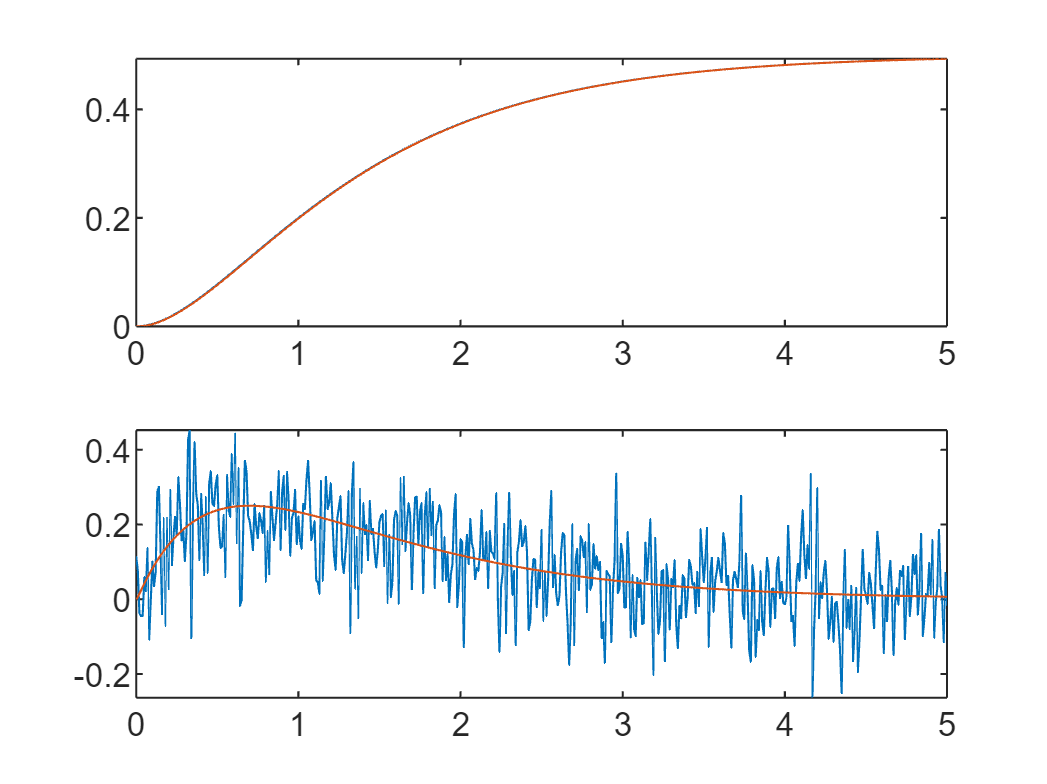

[estimador,K,P] = kalman(ss(Ad,[Bd,eye(2)],C,[0,0,0],Ts),Q,R);
yest = lsim(estimador,[u';y'],t);
figure(2)
subplot(211); plot(t,x(:,1),t,yest(:,2))
subplot(212); plot(t,y,t,yest(:,1))